## Interpolación parabólica sucesiva

clear; clf;
f = @(x) -12-21.*x + 18.*x.^2 - 2.75.*x.^3;
fs = sym(f)

$$fs = -\frac{11\,x^{3}}{4}+18\,x^{2}-21\,x-12$$

df = diff(fs);
dfs = sym(df)

$$dfs = -\frac{33\,x^{2}}{4}+36\,x-21$$

puntosCriticos = roots([-33/4 36 -21])

puntosCriticos =     3.6701
    0.6936


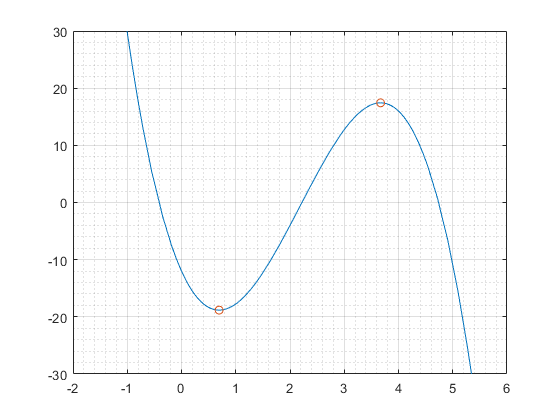

fplot(f);
grid on; grid minor; hold on;
axis([-2 6 -30 30]);
plot(puntosCriticos,f(puntosCriticos),'o'); hold off;

[raiz, iteraciones, fx] = ips(f,2.5, 3, 3.5)

raiz = 3.6701

iteraciones = 8

fx = 17.4353

function [x,i, fx3] = ips(f, x1, x2, x3)
    max_iter = 52;
    tol = sqrt(eps);

    fx1 = f(x1);
    fx2 = f(x2);    

    i = 0;
    cond = true;
    while cond
        fx3 = f(x3);
        x = ((x1+x2)/2) - (((fx2-fx1)*(x3-x1)*(x3-x2))/(2*((x2-x1)*(fx3-fx2) - (fx2-fx1)*(x3-x2))));

        x1 = x2;
        x2 = x3;
        x3 = x;

        fx1 = fx2;
        fx2 = fx3;

        i = i + 1;

        cond = abs((x - x2)/x) > tol && i < max_iter;
    end
end